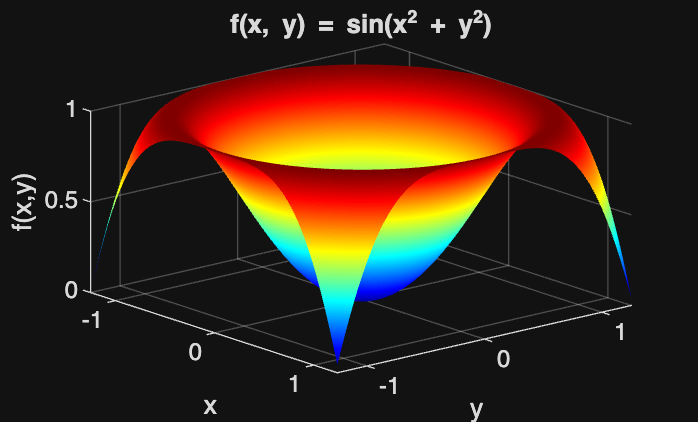

% Mandatory Task
%% Task 1a
% Define non-uniform random x and y coordinates
x_rand = (2*rand(1,200)-1).*sqrt(pi/2);
y_rand = (2*rand(1,200)-1).*sqrt(pi/2);

% Create a uniform grid for 3D surface plotting
[X, Y] = meshgrid(linspace(min(x_rand), max(x_rand), 200), ...
                  linspace(min(y_rand), max(y_rand), 200));

% Calculate function values: f(x,y) = sin(x^2 + y^2)
Z = sin(X.^2 + Y.^2);

% Plotting
figure;
surf(X, Y, Z);
shading interp;
colormap jet;

% Set view angle (azimuth = 50 degrees, elevation = 30 degrees default)
view(50, 30);

% Labels and Title
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('f(x, y) = sin(x^2 + y^2)');
grid on;

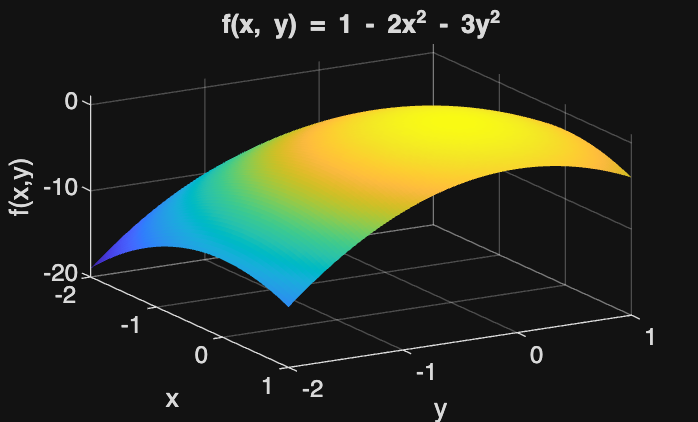


%% Task 1b
% Create grid for x, y in range [-2, 1]
[X, Y] = meshgrid(linspace(-2, 1, 100));

% Calculate function values: f(x,y) = 1 - 2*x^2 - 3*y^2
Z = 1 - 2*X.^2 - 3*Y.^2;

% Plotting
figure;
surf(X, Y, Z);
shading flat;
colormap parula;

% Set view angle (azimuth = 60 degrees, elevation = 30 degrees default)
view(60, 30);

% Labels and Title
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('f(x, y) = 1 - 2x^2 - 3y^2');
grid on;